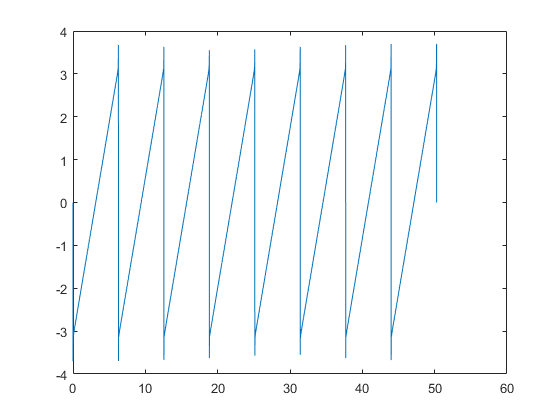

clear all 
t = linspace(0, 16*pi, 2^15);
q=0;
for k = 1:1000
    q = q - 2/k*sin(k.*t);
end

plot(t, q)

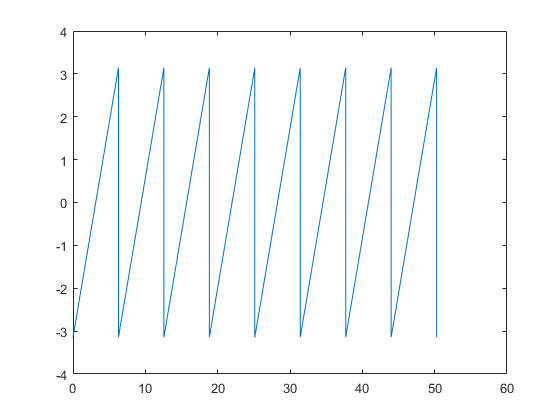

u = pi*sawtooth(t);
plot(t, u);

% steady state filtering 
yss = 0

yss = 0

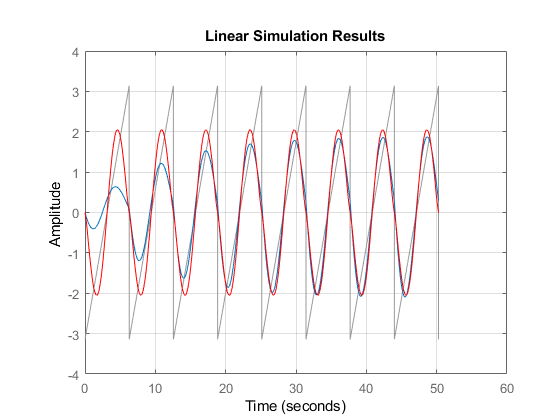

for k = 1:10
    yss = yss + -2/sqrt(25*k^4-49*k^2+25)*sin(k.*t + angle((5*(1 - k^2))/k^2));
end
g = tf([1 0], [5 1 5]);
lsim(g, u, t);
hold on
plot(t, yss, 'r')
hold off
grid on
grid minor
box on